# Power Split Drive Unit

## Basic Simulation

This script runs the most basic simulation to check that the model is properly built.

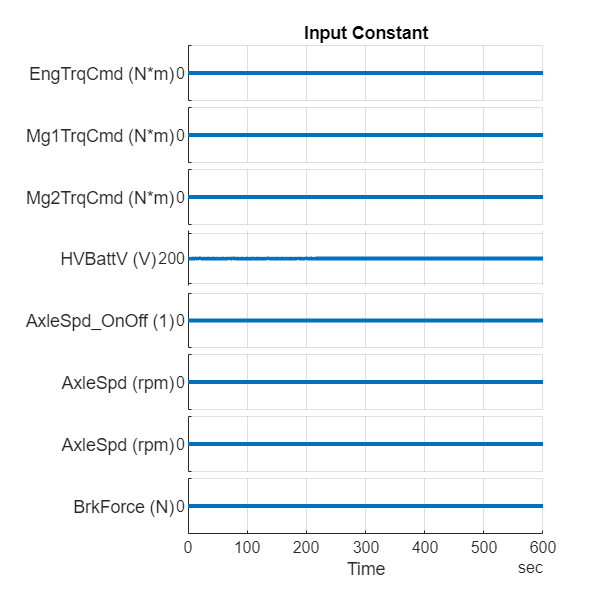

mdl = "PowerSplitDriveUnit_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

PowerSplitDriveUnit_harness_setup

PSDU_SignalBuilder = PowerSplitDriveUnit_InputSignalBuilder("Plot_tf",true);

InpData = Input_Constant(PSDU_SignalBuilder);

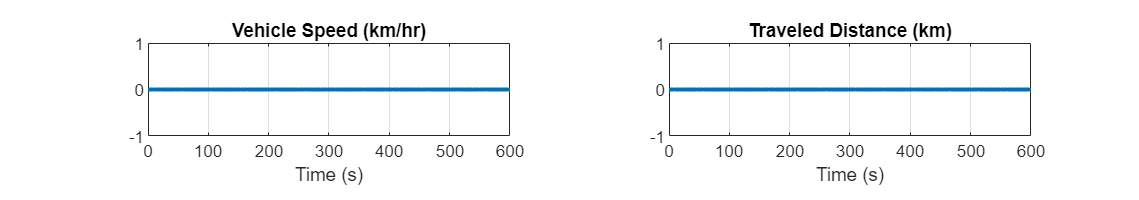

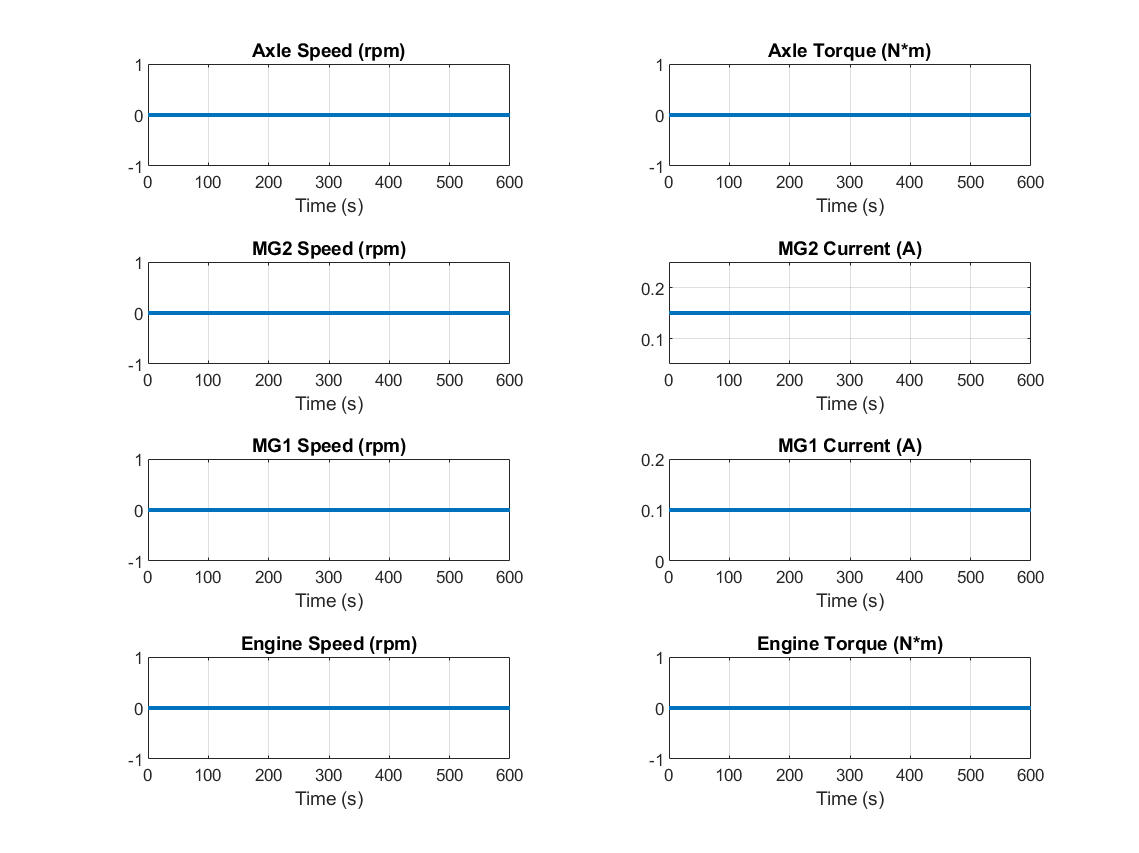

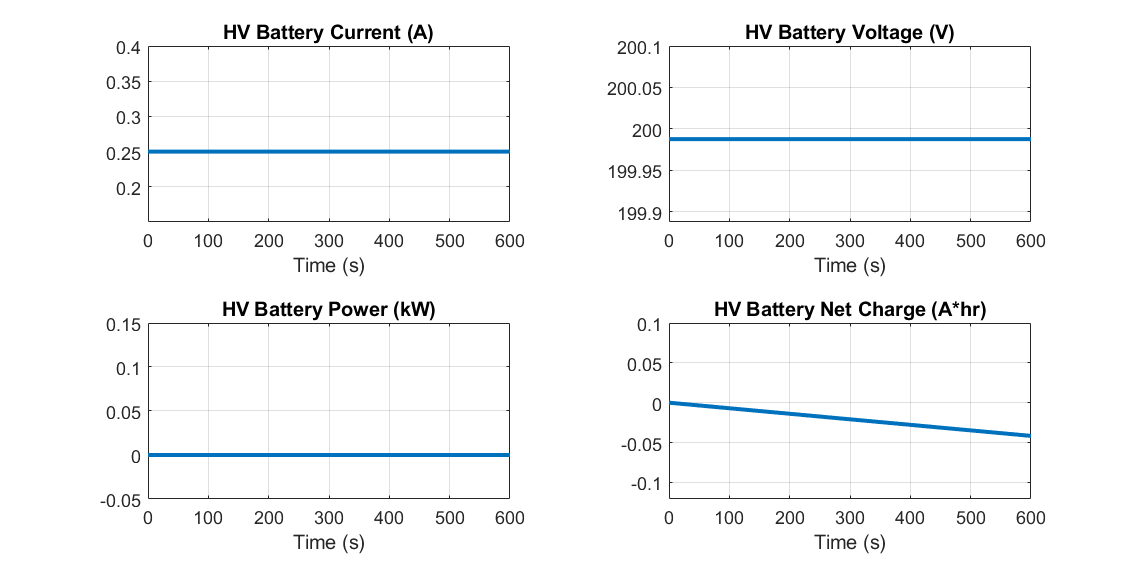


simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn, "PSDU_InputSignals", InpData.Signals);
simIn = setVariable(simIn, "PSDU_InputBus", InpData.Bus);
simIn = setModelParameter(simIn, "StopTime",num2str(InpData.Options.StopTime_s));

simOut = sim(simIn);

PowerSplitDriveUnit_plot_results(simOut.logsout)

*Copyright 2021-2022 The Mathworks, Inc.*